## 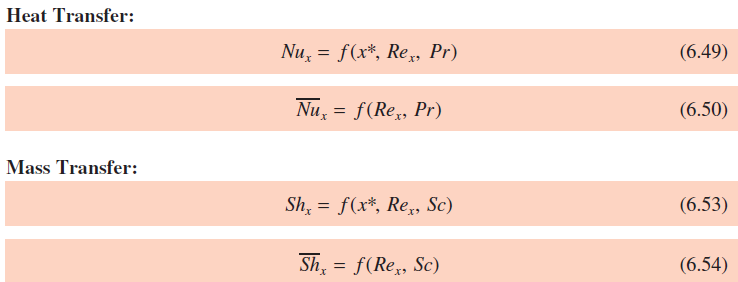

## 

from experimental measurements

## Opgaver

Opgave 7.55

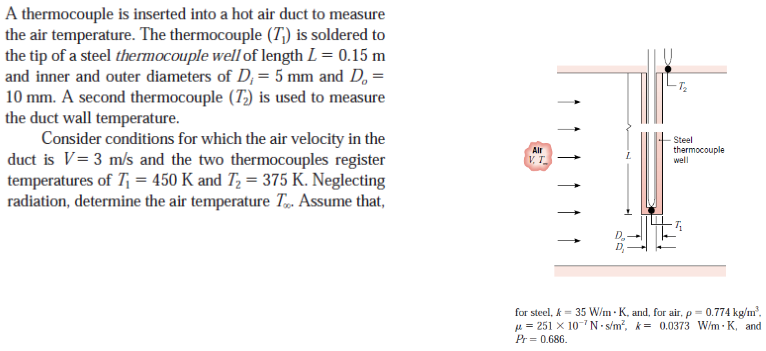

ASSUMPTIONS: 

(1) Steady-state conditions, 

(2) Constant properties, 

(3) One-dimensional conduction along well, 

(4) Uniform convection coefficient, 

(5) Negligible radiation.

L = 0.15; %m længde af thermocouple brønden
Di = 0.005; % m % inner diameter
Do = 0.010; % m % ydre diameter
fluid = 'air'

fluid = 'air'

V = 3; % m/s hastighed af luft
T1 = 450; %K well temperature
T2 = 375; %K wall tempurature
k_staal = 35; %W/m⋅K; stål konductivitet

fra Table a.4

rho = 0.774 % kg/m3 % luft densitet 

rho = 0.7740

mu = 251e-7; % N⋅s/m2 % luft viscosity, kg/s ⋅ m
k_luft = 0.0373; % W/m⋅K luft konductiitet 
Pr = 0.686; % prandtls tal 

n = 0.36;

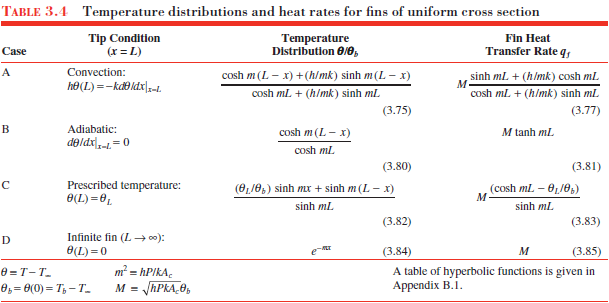

Vi bruger case A ved tipen. og ligningen reduceres derfor

syms T_inf
P = pi * Do

P = 0.0314

Ac = pi * (Do/2)^2 - pi * (Di/2)^2 

Ac = 5.8905e-05

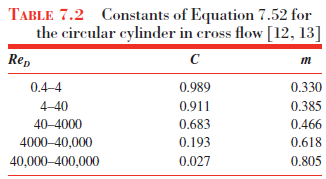

(kun til gennemsnitlig fluid temperatur)

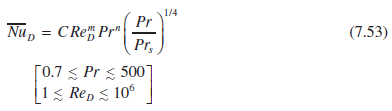(vi bruger denne til at finde $T_\infty$)

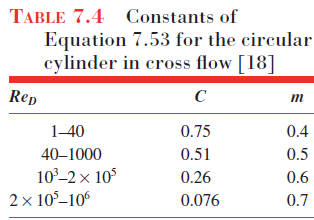

Re = rho * V * Do / mu

Re = 925.0996

C1 = 0.51;
m1 = 0.5;
Nu = C1 * Re^m1 * Pr^n

Nu = 13.5438

h = Nu * k_luft / Do

h = 50.5184

m = sqrt(h * P / (k_staal*Ac))

m = 27.7454

eq = (T1 - T_inf)/(T2 - T_inf) == 1/(cosh(m*L) + (h/(m*k)) * sinh(n*L) )

$$eq = \frac{T_{\inf}-450}{T_{\inf}-375}=\frac{8297108075969569}{288230376151711744}$$

vpa(solve(eq, T_inf),6) - 273.15

$$ans = 179.07296945973939727991819381714$$

vpa(solve(eq, T_inf),6)

$$ans = 452.223$$

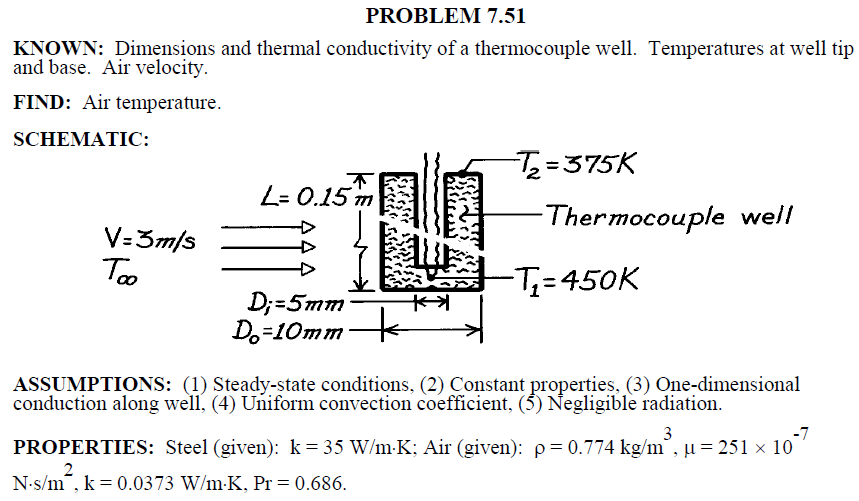

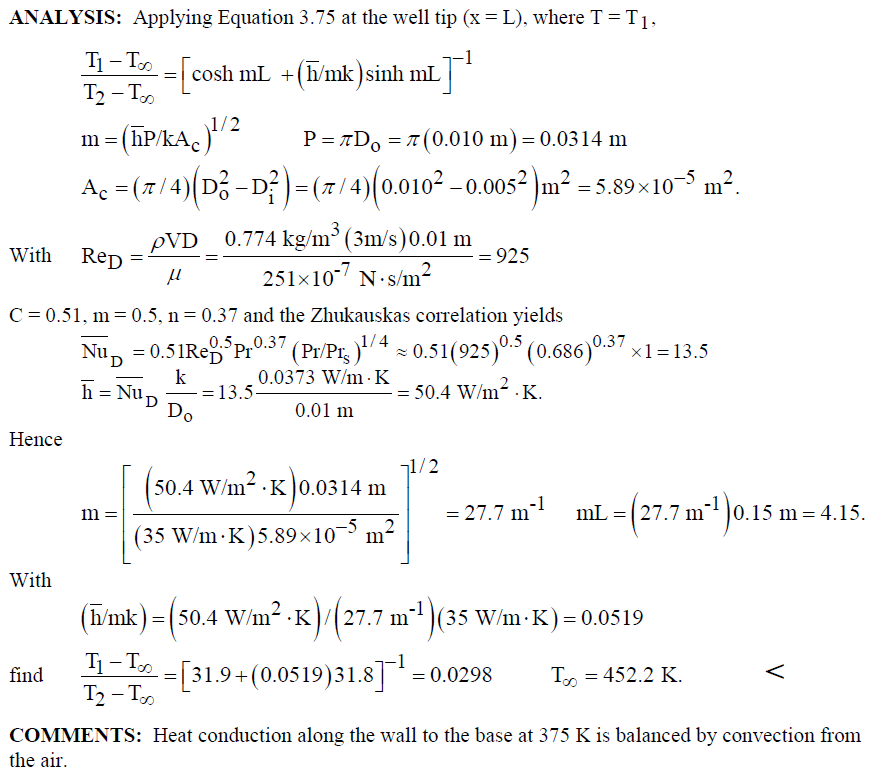

Opgave 7.75

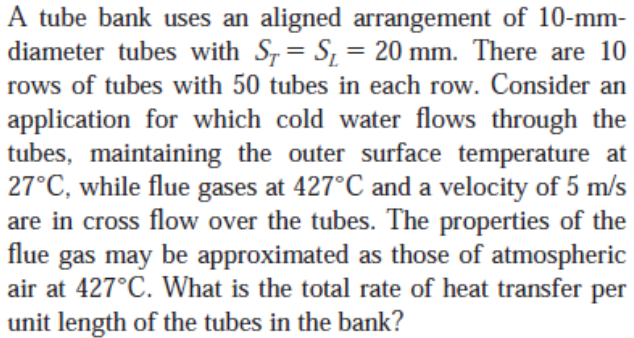

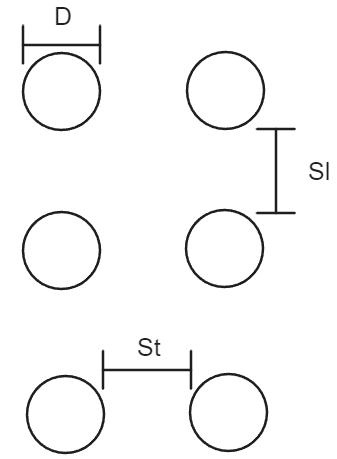

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5
fluid = 'air'

fluid = 'air'


D = 0.010; %m % diameter
St = 0.020; % afstand imellem rør
Sl = St; % afstand imellem rør
N_t = 50;
N_l = 10;
N = N_t * N_l; % antal tubes
T_tube = 27 + 273.15; % K % overflade temperaturen af tubes
T_gas = 427 + 273.15; % K % Gas temperaturen
V = 5; % m/s hastigheden af gassen over rørerne
k = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_gas, fluid)

k =      0.051764


c_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_gas, fluid); %specificHeat_p
mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_gas, fluid); %Dynamisk viscositet
rho = CoolProp.PropsSI('D', 'P', P, 'T', T_gas, fluid); %Densitet


syms L
A = pi * D * L

$$A = \frac{\pi \,L}{100}$$

V_max = (Sl)/(D) * V

V_max =     10


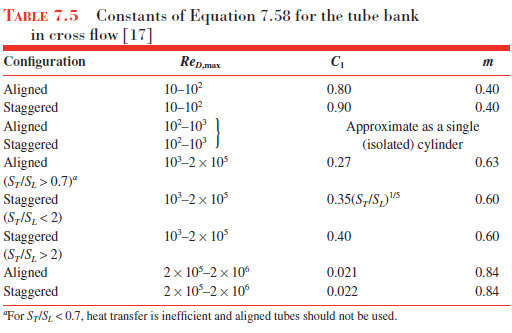

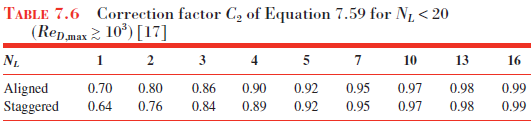

Re_Dmax = rho * V_max * D / mu

Re_Dmax =        1474.4


C1 = 0.27;
C2 = 0.97;
m1 = 0.63;
Pr = 0.707;
Pr_s = 0.695;
Nu = C1* C2 * Re_Dmax^m1 * Pr^0.36 * (Pr/Pr_s)^(1/4)

Nu =        23.016


h = Nu * k / D

h =        119.14


heat transer per meter

T_s = T_tube;
T_i = T_gas;
syms T_0
T_0_eq = (T_s - T_0) / (T_s - T_i) == exp(-(pi * D * N * h) / ...
    (rho * V * N_t * St * c_p) )

$$T\_0\_eq = \frac{T_{0}}{400}-\frac{6003}{8000}=\frac{1128500877752355}{2251799813685248}$$

T_0 = vpa(solve(T_0_eq, T_0),6)

$$T\_0 = 500.612$$


DT_lm = ( (T_s -T_i) - (T_s -T_0) ) / log( (T_s - T_i) / (T_s - T_0))

$$DT\_lm = -288.83396450839892433664014752855$$

q = double(N * DT_lm * A/L * h) % W/m

q =   -5.4053e+05